# Dinámica del sistema de Lorenz

## Atractor del Lorenz

clear all
% Definir los parámetros del sistema de Lorenz
sigma = 10;
rho = 28;
beta = 8/3;

% Definir las ecuaciones del sistema de Lorenz
lorenz_eqs = @(t, x) [sigma*(x(2) - x(1)); ...
                      x(1)*(rho - x(3)) - x(2); ...
                      x(1)*x(2) - beta*x(3)];

% Encontrar los puntos de equilibrio (donde las derivadas son cero)
eq1 = [0 0 0];
eq2 = [ sqrt(beta*(rho-1))   sqrt(beta*(rho-1)) (rho-1)];
eq3 = [-sqrt(beta*(rho-1))  -sqrt(beta*(rho-1)) (rho-1)];

% Opciones para la integración de las ecuaciones diferenciales
opts = odeset('abstol', 1e5*eps, 'reltol', 100*eps);

% Tiempo de integración
tspan = [0:.01:50];

% Condiciones iniciales
initial_conditions = rand(1, 3);

% Resolver las ecuaciones de Lorenz para cada conjunto de condiciones iniciales
[t, x] = ode45(lorenz_eqs, tspan, initial_conditions, opts);


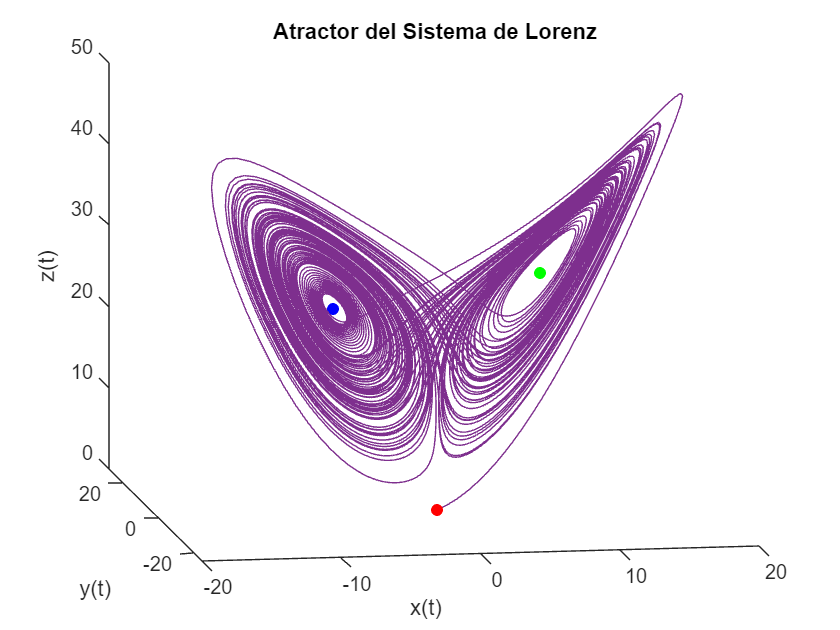

% Dibujar el atractor de Lorenz
figure;
hold on;
% Graficar los puntos de equilibrio en el atractor
scatter3(eq1(1), eq1(2), eq1(3), 'r', 'filled');
scatter3(eq2(1), eq2(2), eq2(3), 'g', 'filled');
scatter3(eq3(1), eq3(2), eq3(3), 'b', 'filled');
plot3(x(:,1), x(:,2), x(:,3));
xlabel('x(t)');
ylabel('y(t)');
zlabel('z(t)');
title('Atractor del Sistema de Lorenz');
view([-9.5 13.0]);

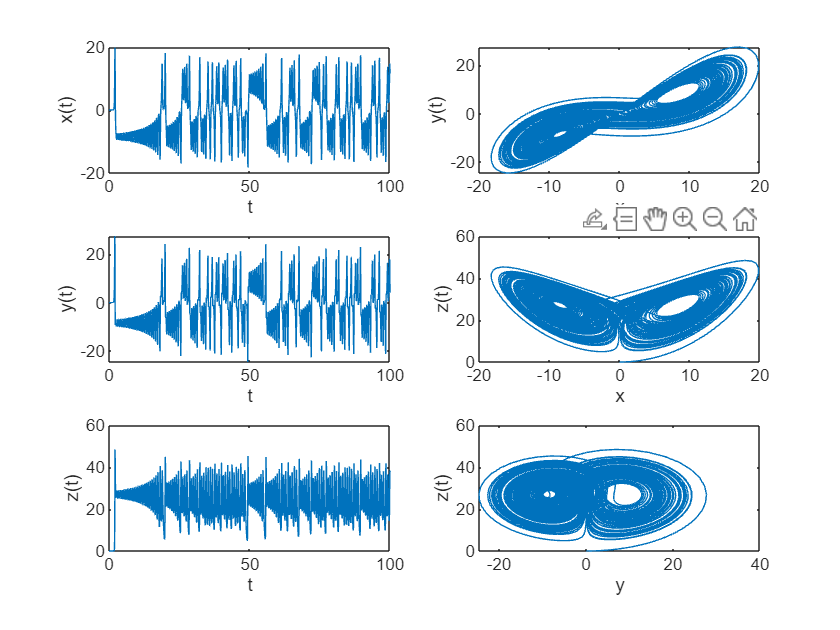


figure;
subplot(3,2,1);
plot(t,x(:,1));xlabel('t');ylabel('x(t)')
subplot(3,2,2);
plot(x(:,1),x(:,2));xlabel('x');ylabel('y(t)')
subplot(3,2,3);
plot(t,x(:,2));xlabel('t');ylabel('y(t)')
subplot(3,2,4);
plot(x(:,1),x(:,3));xlabel('x');ylabel('z(t)')
subplot(3,2,5);
plot(t,x(:,3));xlabel('t');ylabel('z(t)')
subplot(3,2,6);
plot(x(:,2),x(:,3));xlabel('y');ylabel('z(t)')

## Bifurcación del sistema de Lorenz

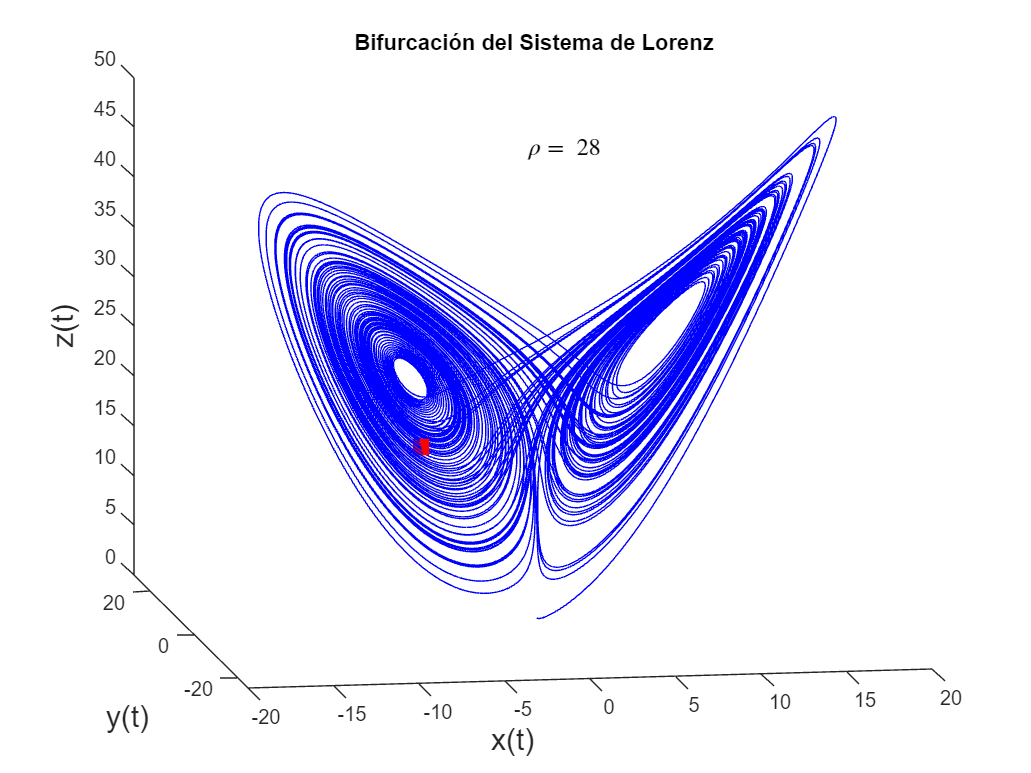

clear all
% Definir las ecuaciones del sistema de Lorenz
sigma = 10;
rho = 28;
beta = 8/3;

% Opciones para la integración de las ecuaciones diferenciales
opts = odeset('abstol', 1e5*eps, 'reltol', 100*eps);

lorenz_eqs = @(t, x, rho) [sigma*(x(2) - x(1)); ...
                        x(1)*(rho - x(3)) - x(2); ...
                        x(1)*x(2) - beta*x(3)];

% Configuración inicial del gráfico
% Configuración inicial de la gráfica de dinámicas
figure('Position', [100, 100, 800, 600]); % Definir el tamaño del gráfico

hold on;
view([-9.5 13.0]);
xlabel('x(t)', 'FontSize', 15);
ylabel('y(t)', 'FontSize', 15);
zlabel('z(t)', 'FontSize', 15);
title('Bifurcación del Sistema de Lorenz');

% Punto inicial de la trayectoria
last_point = plot3(NaN, NaN, NaN, 'rs', 'MarkerSize', 10,'MarkerFaceColor','r');

dynamics = plot3(NaN, NaN, NaN,'b');
% Número de fotogramas
numframes = 50;
rho_values = linspace(0.1,28,numframes);
% Animación de la bifurcación
for j = 1:numframes 
    % Actualizar el valor de r
    r = rho_values(j); % r va cambiando
    
    % Resolver las ecuaciones de Lorenz
    [t,y] = ode45(@(t,y) lorenz_eqs(t,y,r),[0 100],rand(3,1),opts);
        

    % Borrar el punto final de la iteración anterior
    delete(last_point);
    
    % Dibujar el punto final de la trayectoria actual
    last_point = plot3(y(end,1), y(end,2), y(end,3), 'rs', 'MarkerSize', 10,'MarkerFaceColor','r');
    
    % Actualizar los datos de la gráfica de dinámicas
    dynamics.XData = y(:,1);
    dynamics.YData = y(:,2);
    dynamics.ZData = y(:,3);
    
    % Borrar el texto anterior
    delete(findobj(gcf,'type','text'));
    
    % Mostrar el valor de r en el gráfico
    text(mean(y(:,1)), mean(y(:,2)), max(y(:,3)), ['$\rho =$ ', num2str(r)], 'FontSize', 12,'Interpreter','latex');
    
    % Actualizar la vista del gráfico
    drawnow;
end

## Sensibilidad a las Condiciones Iniciales

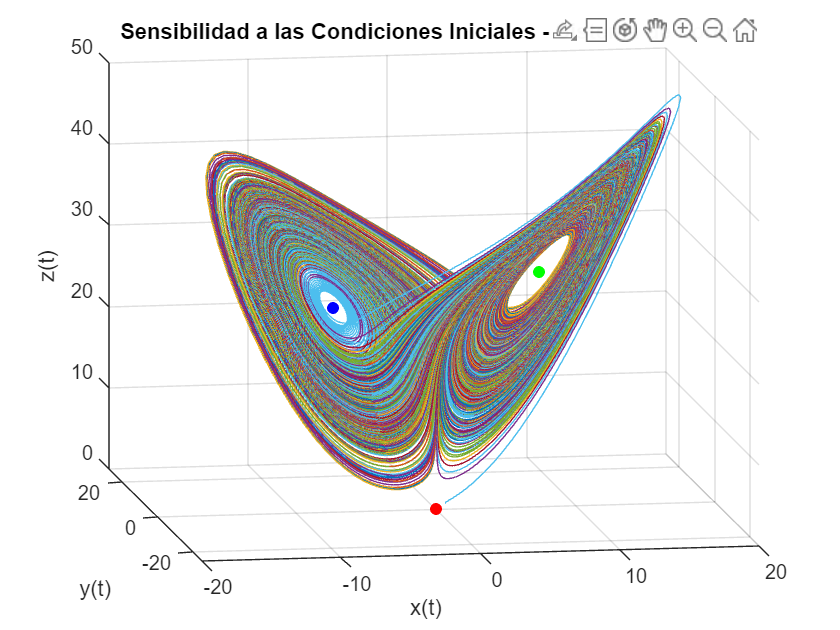

clear all
% Definir las ecuaciones del sistema de Lorenz
sigma = 10;
rho = 28;
beta = 8/3;

lorenz_eqs = @(t, x) [sigma*(x(2) - x(1)); ...
                        x(1)*(rho - x(3)) - x(2); ...
                        x(1)*x(2) - beta*x(3)];

% Encontrar los puntos de equilibrio (donde las derivadas son cero)
eq1 = [0 0 0];
eq2 = [sqrt(beta*(rho-1)) sqrt(beta*(rho-1)) (rho-1)];
eq3 = [-sqrt(beta*(rho-1)) -sqrt(beta*(rho-1)) (rho-1)];

num_trajectories = 10;

% Opciones para la integración de las ecuaciones diferenciales
opts = odeset('abstol', 1e5*eps, 'reltol', 100*eps);

% Tiempo de integración
tspan = [0:.01:100];

% Escala para generar condiciones iniciales cercanas
scale = 1e-9;

% Condiciones iniciales (generar números aleatorios en un rango pequeño y escalarlos)
initial_conditions = rand(1, 3);

% Resolver las ecuaciones de Lorenz para cada conjunto de condiciones iniciales
figure;
hold on;
% Graficar los puntos de equilibrio en el atractor
scatter3(eq1(1), eq1(2), eq1(3), 'r', 'filled');
scatter3(eq2(1), eq2(2), eq2(3), 'g', 'filled');
scatter3(eq3(1), eq3(2), eq3(3), 'b', 'filled');

for i = 1:num_trajectories
    x0 = initial_conditions + rand*scale;
    [t, x] = ode45(lorenz_eqs, tspan, x0, opts);
    plot3(x(:,1), x(:,2), x(:,3));
    xlabel('x(t)');
    ylabel('y(t)');
    zlabel('z(t)');
    title('Sensibilidad a las Condiciones Iniciales - Sistema de Lorenz');
    view([-9.5 13.0]);
    grid on;    
    drawnow;
end

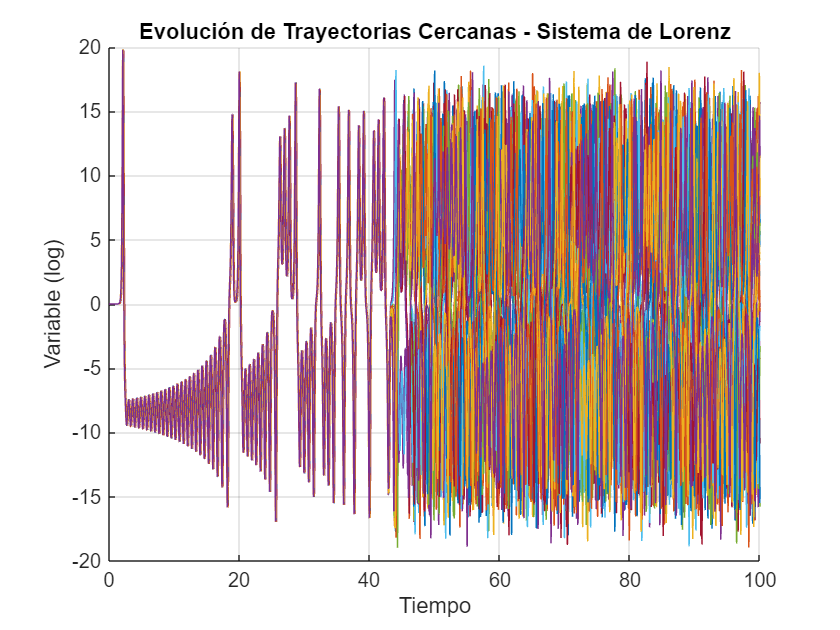



% Configuración del gráfico
num_trajectories = 25;

% Variable a representar (por ejemplo, la coordenada x)
variable = zeros(num_trajectories, length(tspan));
final_states = zeros(num_trajectories, 3);
% Escala para generar condiciones iniciales cercanas
scale = 1e-9;

% Condiciones iniciales (generar números aleatorios en un rango pequeño y escalarlos)
initial_conditions = rand(num_trajectories, 3) * scale;


% Resolver las ecuaciones de Lorenz para cada conjunto de condiciones iniciales
for i = 1:num_trajectories
    [~, x] = ode45(lorenz_eqs, tspan, initial_conditions(i,:), opts);
    variable(i,:) = x(:,1);         % recoger la posición x
    final_states(i,:) = x(end,:);   %recoger la posición final de x
end

% Graficar la variable en función del tiempo (usando escala logarítmica)
figure;
hold on;
for i = 1:num_trajectories
    semilogy(tspan, variable(i,:));
end

xlabel('Tiempo');
ylabel('Variable (log)');
title('Evolución de Trayectorias Cercanas - Sistema de Lorenz');
grid on;

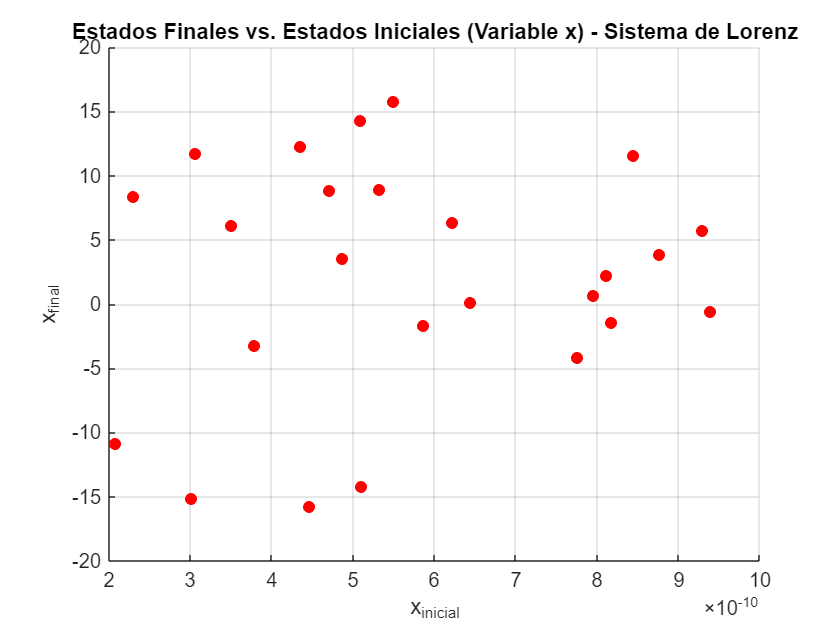

% Gráfico de los estados finales frente a los estados iniciales
figure;
scatter(initial_conditions(:,1), final_states(:,1), 'filled', 'MarkerFaceColor', 'r');
xlabel('x_{inicial}');
ylabel('x_{final}');
title('Estados Finales vs. Estados Iniciales (Variable x) - Sistema de Lorenz');
grid on;

%axis equal